# Estimation of the bilinear form y∗f(A)x for Hermitian matrices

## EE5120 Applied Linear Algebra for I for EE

##  Project

Jul - Nov 2020 Semester

S Aniruddha (EP18B029)

### ABSTRACT

The goal of this project is to reproduce a subset of results from the [work published by Fika et al.](https://www.sciencedirect.com/science/article/pii/S002437951500511X) in 2016. Specifically, I replicate the tables 2, 3, 4 and 7. These results are obtained for the mhd1280b matrix (dimension 1280), obtained by the University of Florida Sparse Matrix Collection [2]. The matrix has applications in electromagnetic problems and it is Hermitian positive definite.

### INTRODUCTION

Consider a hermitian matrix A of dimension p and complex vectors x, y of length p. Let f be a smooth function defined on the spectrum of matrix A. An extrapolation based approach is used to estimate the bilinear form y∗f(A)x. The computation of y∗f(A)x arises in network analysis, in machine learning, in statistics, etc. Using this estimate for  y∗f(A)x, estimates for the following problems can also be derived:

- Finding elements of the matrix f(A)

- Finding trace of the matrix f(A)

- Determinant of matrix A

- Calculating the bilinear form  y∗A^-1*x (used in signal processing, nuclear physics, quantum mechanics, solid state physics, etc.)

and more...

### FAMILIES OF ESTIMATES USING EXTRAPOLATION

- Hermitian matrix: A ∈ $C^{p\;\times \;p}$

- Vectors: x, y ∈ $C^p$

- The maximum and the minimum eigenvalues of a A: λ1 and λp respectively

- Spectral decomposition of A: $A=V\Lambda V^* =\sum_{k=1}^p \lambda_p v_k v_k^*$ 

- 
$$f\left(A\right)=V\;f\left(\Lambda \right)V^*$$


- In order the matrix f(A)to be also Hermitian, it is necessary to assume that the spectrum of this matrix takes only real values i.e. f(Λ) ∈ $R^{p\;\times \;p}$. Thus, in the case of functions such as the logarithm or the square root, we must assume that the matrix A ∈ $C^{p\;\times \;p}$ should have no eigenvalues on the closed negative real axis.

- The moments of matrix A are defined as: 

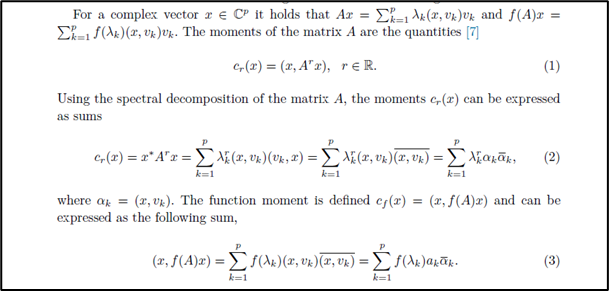

*excerpt from Page 143 of the paper*

Consider as interpolation conditions one or two terms of the summation in the moments of A relation for some moments cn(x) with a non negative integer index n. Then, the moments cf(x) can be estimated by extrapolating these interpolation conditions to the formula for cf(x). 

In what follows, the moments cr(x) and cf(x) will be denoted as cr and cf, respectively, and all the denominators of the estimates are assumed to be different from zero.

### ONE TERM ESTIMATES

The one term estimates for cf can be derived by retaining one term in the summation (3): 


$${\left(x,f\left(A\right)x\right)\;=\;c}_f \approx f\left(l\right){\left|a\right|}^2 \ldotp$$


where the unknowns $l$ and $\left|a_i \right|$ are determined by imposing the following interpolation conditions:

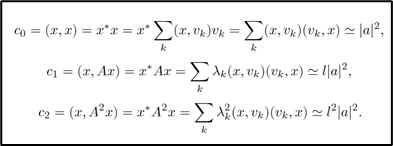

*- excerpts from Page 146 of the paper *

From this system of equation, we can derive the expression for the family of one term estimates as follows:

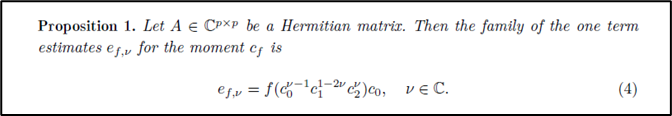

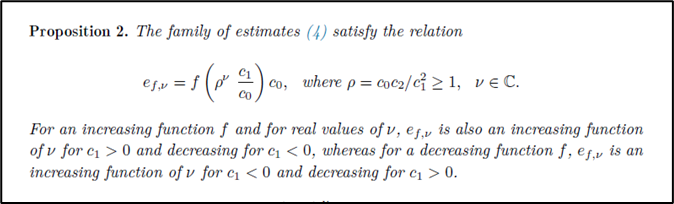

*- excerpts from Page 144 of the paper *

We can also derive the following results for the one term estimates:

(a)

(b)

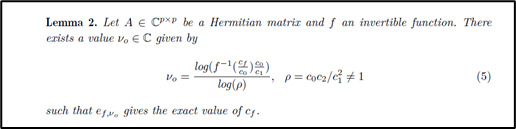

*- excerpts from Page 145 of the paper *

-  $\nu_0$ in expression 5 above is called the optimal value of  $\nu_0$

The one term estimate $e_{f,\nu }$  for $\nu$ = $\nu_0$ gives the exact value of the function moment $c_f$ in only one matrix-vector product. But the computation of $\nu_0$ from formula (5) cannot be obtained in practice, since it requires the a priori knowledge of the exact moment $c_f$. However, for Hermitian positive definite matrices, bounds for $\nu_0$ can be derived for various $f\left(A\right)$. For $f\left(A\right)$ = $A^{-1}$, a direct approximation for  $\nu_0$ can be obtained.

Here are the relevant expressions for bounds of $\nu_0$ from the paper that are used in this project: 

(a)

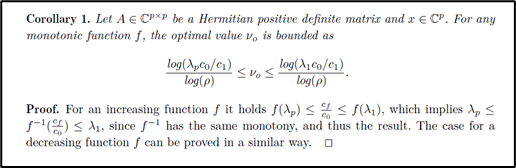

(b)

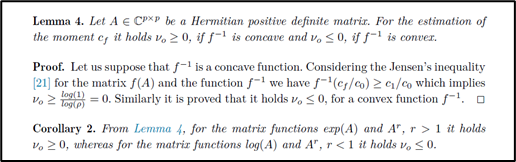

(c)

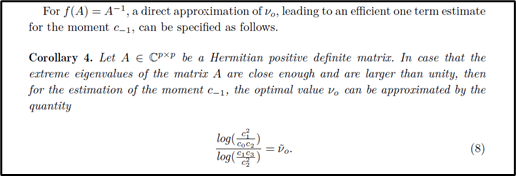

*excerpts from Page 147-148 of the paper*

### TWO TERM ESTIMATES

The two term estimates for cf can be derived by retaining two terms in the summation (3): 


$$c_f \approx f\left(l_1 \right){\left|a_2 \right|}^2 +f\left(l_2 \right){\left|a_2 \right|}^2 \ldotp$$


The unknowns $l_i$ and ${\left|a_i \right|}^2$, i =1, 2, are determined by imposing the following interpolation conditions:

The preceding interpolation conditions mean, in fact, that the moments cn(x) satisfy the following difference equation:

We can then solve the system of equations to get the values for r, q, $l_i$ and ${\left|a_i \right|}^2$, i =1, 2 that satisfy the interpolation conditions.  

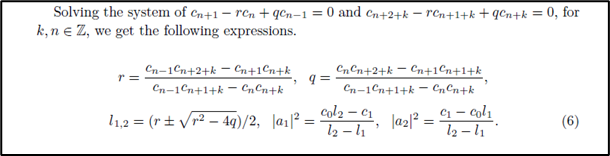

From this, we obtain the family of the two term estimates $e_{f,\;n,\;k}$ for the moment cf, as shown below:

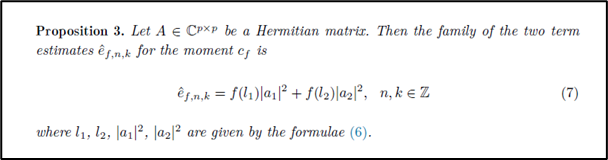

*- excerpts from Page 146 of the paper* 

### TRACE ESTIMATES

The one and two term estimates can be used to find the trace of the matrix f(A) using the expression below [3]:

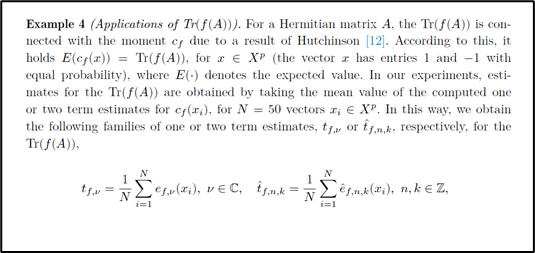

*- excerpt from Page 153 of the paper* 

Please note that since the algorithm for trace estimation involves randomized choices for x, exact replication of results is not possible. I have used the randi function and the output estimate is different for each instance of execution of the code. (For the results of table 7)

uiimport('mhd1280b.mat')

A = full(Problem.A)

A =    2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.2525 + 0.0000i   0.00

[U,Lambda_A] = eig(A);
invA = inv(A)

invA = 	1.0e+10 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 +

sqrtA = sqrtm(A)

sqrtA =    1.4142 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.4890 + 0.0000i  -

logA = logm(A)

logA =    0.6931 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.4982 + 0.0000i  -0

expA = expm(A)

expA = 	1.0e+30 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 +

z = eig(A);
Lambda_B = diag(z ./ (1 + exp(z - 12*ones(1280,1))));
Lambda_C = diag(z ./ ( 1 + exp(z - 20*ones(1280,1))));
B = U * Lambda_B * U';
C = U * Lambda_C * U';
I = eye(1280);
e25 = I(:,25);
e1 = I(:,1);
e8 = I(:,8);
e3 = I(:,3);
e100 = I(:,100);
e900 = I(:,900);
e1000 = I(:,1000);
e1203 = I(:,1203);
e565 = I(:,565);
e7 = I(:,7);
e500 = I(:,500);

### NUMERICAL RESULTS

- One term estimates: The authors obtained one term estimates by considering the mean value νm of some values of ν in the intervals of Corollaries 1–3 (from the paper). In case that $f\left(A\right)$ = $A^{-1}$, from Corollary 4, the value of νo was assigned to νm.

- **Note:** Since the value of vm chosen by the authors  for functions other than $A^{-1}$ is not known, I have calculated the value of vm for which we get the relative error results given in the paper, and verified that the vm I found lies within the theoretically obtained bounds for v0.

- Two term estimates ${e\;}_{f,\;n,\;k}$: For 2 term estimates, the values of n = 1, k = 0, 2 were selected.

In Tables 2, 3 and 4, estimates for the entries ${f\left(A\right)}_{i,i}$ are presented. In all the examples, matlab code for the estimation comes first. It is followed by a summary of obtained result and the expected result from the paper.

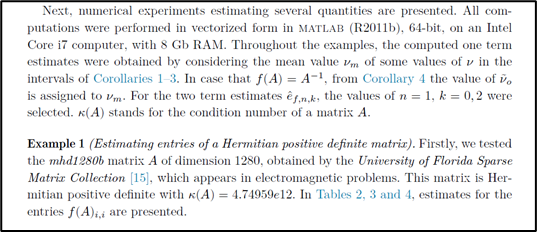

*excerpt from Page 151 of the paper*

#### (I)Table 2: $f\left(A\right)$ = $A^{-1}$, $f\left(A\right)$ = $A^{\frac{1}{2}}$

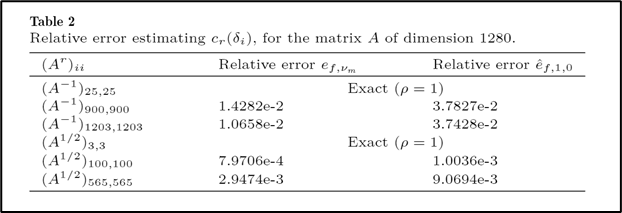

*Table from Page 152 of the paper*

${A^{-1} }_{\left(25,25\right)}$:

cf = e25' * invA * e25

cf = 0.5000

c0 = e25' * e25;
c1 = e25' * A * e25;
c2 = e25' * A * A * e25;
ro = (c0*c2)/(c1^2)

ro = 1


vm = 1;
estimate_1 = ((ro^vm) * c1 / c0)^-1 * c0

estimate_1 = 0.5000

format long
relative_error_1term = abs((estimate_1 - cf)/cf)

relative_error_1term =      0


format short

Here, since $\rho =1$, the one-term estimate gives the exact value for cf.

Relative error for 1 term estimate = 0

Relative error result from paper = 0

${A^{-1} }_{\left(900,900\right)}$, 1 term estimate:

cf = e900' * invA * e900

cf = 792.2908

c0 = e900' * e900;
c1 = e900' * A * e900;
c2 = e900' * A * A * e900;
c3 = e900' * A * A * A * e900;
ro = (c0*c2)/(c1^2);

vm = log((c1^2)/(c0 * c2)) / log((c1 * c3)/(c2^2));
estimate_1 = ((ro^vm) * c1 / c0)^-1 * c0

estimate_1 = 8.0361e+02 + 1.1738e-29i

format long
relative_error_1term = abs((estimate_1 - cf)/cf)

relative_error_1term =    0.014282379613976


format short

Relative error for 1 term estimate = `0.014282379613976`

Relative error from paper = 1.4282e-2

${A^{-1} }_{\left(900,900\right)}$, 2 term estimate:

cf = e900' * invA * e900
c0 = e900' * e900;
c1 = e900' * A * e900;
c2 = e900' * A * A * e900;
c3 = e900' * A * A * A * e900;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * (l1)^-1 + x2 * (l2)^-1
format long
relative_error_2term = abs((estimate_2 - cf)/cf)
format short

Relative error for 2 term estimate = `0.037826862171817`

Relative error from paper = 3.7827e-2

${A^{-1} }_{\left(1203,1203\right)}$, 1 term estimate:

cf = e1203' * invA * e1203

cf = 501.2890

c0 = e1203' * e1203;
c1 = e1203' * A * e1203;
c2 = e1203' * A * A * e1203;
c3 = e1203' * A * A * A * e1203;
ro = (c0*c2)/(c1^2);

vm = log((c1^2)/(c0 * c2)) / log((c1 * c3)/(c2^2));
estimate_1 = ((ro^vm) * c1 / c0)^-1 * c0

estimate_1 = 4.9595e+02 + 4.4855e-29i

format long
relative_error_1term = abs((estimate_1 - cf)/cf)

relative_error_1term =    0.010657716339714


format short

Relative error for 1 term estimate = `0.010657716339714`

Relative error from paper = 1.0658e-2

${A^{-1} }_{\left(1203,1203\right)}$, 2 term estimate:

cf = e1203' * invA * e1203

cf = 501.2890

c0 = e1203' * e1203;
c1 = e1203' * A * e1203;
c2 = e1203' * A * A * e1203;
c3 = e1203' * A * A * A * e1203;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * (l1)^-1 + x2 * (l2)^-1

estimate_2 = 4.8253e+02 + 3.3375e-29i

format long
relative_error_2term = abs((estimate_2 - cf)/cf)

relative_error_2term =    0.037428470419433


format short

Relative error for 2 term estimate = `0.037428470419433`

Relative error from paper = 3.7428e-2

${A^{\frac{1}{2}} }_{\left(3,3\right)}$, 1 term estimate:

cf = e3' * sqrtA * e3

cf = 1.4142

c0 = e3' * e3;
c1 = e3' * A * e3;
c2 = e3' * A * A * e3;
ro = (c0*c2)/(c1^2)

ro = 1


vm = 1;
estimate_1 = ((ro^vm) * c1 / c0)^0.5 * c0

estimate_1 = 1.4142

format long
relative_error_1term = abs((estimate_1 - cf)/cf)

relative_error_1term =      1.413083212815399e-15


format short

Here, since $\rho =1$, the one-term estimate gives the exact value for cf.

Relative error for 1 term estimate = `1.413083212815399e-15 (orders of magnitude smaller)`

Relative error from paper = 0

${A^{\frac{1}{2}} }_{\left(100,100\right)}$, 1 term estimate:

cf = e100' * sqrtA * e100

cf = 0.1144

c0 = e100' * e100;
c1 = e100' * A * e100;
c2 = e100' * A * A * e100;
ro = (c0*c2)/(c1^2);

lambda_1 = Lambda_A(1280,1280);
lambda_p = Lambda_A(1,1);
vm_lower = log(lambda_p * c0/c1)/log(ro)

vm_lower = -1.4325e+02 - 3.0873e-32i

vm_higher = 0

vm_higher = 0

vm = (vm_lower + vm_higher) / 2;
estimate_1 = ((ro^vm) * c1 / c0)^0.5 * c0;
relative_error1 = abs((estimate_1 - cf)/cf);

vm_paper = -0.218185636745234

vm_paper = -0.2182

estimate_1_paper = ((ro^vm_paper) * c1 / c0)^0.5 * c0

estimate_1_paper = 0.1145 + 0.0000i

format long
relative_error_1term_paper = abs((estimate_1_paper - cf)/cf)

relative_error_1term_paper =      7.970599999999081e-04


format short

- vm theoretical lower limit =` -1.4325e+02 `

- vm theoretical upper limit =` 0`

- vm used in paper = -0.218185636745234

Relative error for 1 term estimate = `7.970599999999081e-04`

Relative error from paper = 7.9706e-4

${A^{\frac{1}{2}} }_{\left(100,100\right)}$, 2 term estimate:

cf = e100' * sqrtA * e100

cf = 0.1144

c0 = e100' * e100;
c1 = e100' * A * e100;
c2 = e100' * A * A * e100;
c3 = e100' * A * A * A * e100;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * (l1)^0.5 + x2 * (l2)^0.5

estimate_2 = 0.1145 + 0.0000i

format long
relative_error_2term = abs((estimate_2 - cf)/cf)

relative_error_2term =    0.001003586608672


format short

Relative error for 2 term estimate = `0.001003586608672`

Relative error from paper = 1.0036e-3 

${A^{\frac{1}{2}} }_{\left(565,565\right)}$, 1 term estimate:

cf = e565' * sqrtA * e565

cf = 0.1067

c0 = e565' * e565;
c1 = e565' * A * e565;
c2 = e565' * A * A * e565;
ro = (c0*c2)/(c1^2);

lambda_1 = Lambda_A(1280,1280);
lambda_p = Lambda_A(1,1);
vm_lower = log(lambda_p * c0/c1)/log(ro)

vm_lower = -84.2193 - 0.0000i

vm_higher = 0

vm_higher = 0

vm = (vm_lower + vm_higher) / 2;
estimate_1 = ((ro^vm) * c1 / c0)^0.5 * c0;
relative_error1 = abs((estimate_1 - cf)/cf);

vm_paper = -0.1385676806

vm_paper = -0.1386

estimate_1_paper = ((ro^vm_paper) * c1 / c0)^0.5 * c0

estimate_1_paper = 0.1070 + 0.0000i

format long
relative_error_1term_paper = abs((estimate_1_paper - cf)/cf)

relative_error_1term_paper =    0.002947400000259


format short

- vm theoretical lower limit =` -84.2193`

- vm theoretical upper limit =` 0`

- vm used in paper = -0.1385676806

Relative error for 1 term estimate = `0.002947400000259`

Relative error from paper = 2.9474e-3

${A^{\frac{1}{2}} }_{\left(565,565\right)}$, 2 term estimate:

cf = e565' * sqrtA * e565

cf = 0.1067

c0 = e565' * e565;
c1 = e565' * A * e565;
c2 = e565' * A * A * e565;
c3 = e565' * A * A * A * e565;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * (l1)^0.5 + x2 * (l2)^0.5

estimate_2 = 0.1077 - 0.0000i

format long
relative_error_2term = abs((estimate_2 - cf)/cf)

relative_error_2term =    0.009069356858282


format short

Relative error for 2 term estimate = `0.009069356858282`

Relative error from paper = 9.0694e-3

#### (II)Table 3: $f\left(A\right)$ = $\log \left(A\right)$

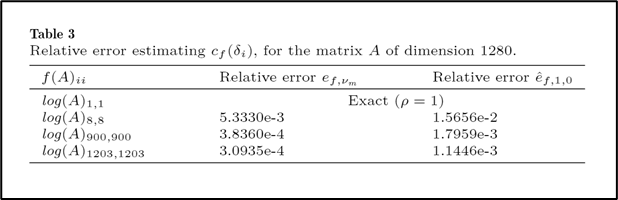

*Table from Page 152 of the paper*

${\textrm{logA}}_{\left(1,1\right)}$, 1 term estimate:

cf = e1' * logA * e1

cf = 0.6931

c0 = e1' * e1;
c1 = e1' * A * e1;
c2 = e1' * A * A * e1;
ro = (c0*c2)/(c1^2)

ro = 1


vm = 1;
estimate_1 = log((ro^vm) * c1 / c0) * c0

estimate_1 = 0.6931

format long
relative_error_1term = abs((estimate_1 - cf)/cf)

relative_error_1term =      0


format short

Here, since $\rho =1$, the one-term estimate gives the exact value for cf.

Relative error for 1 term estimate = 0

Relative error result from paper = 0

${\textrm{logA}}_{\left(8,8\right)}$, 1 term estimate:

cf = e8' * logA * e8

cf = -10.3485

c0 = e8' * e8;
c1 = e8' * A * e8;
c2 = e8' * A * A * e8;
ro = (c0*c2)/(c1^2);

lambda_1 = Lambda_A(1280,1280);
lambda_p = Lambda_A(1,1);
vm_lower = log(lambda_p * c0/c1)/log(ro)

vm_lower = -1.7179 - 0.0000i

vm_higher = 0

vm_higher = 0

vm = (vm_lower + vm_higher) / 2;
estimate_1 = log((ro^vm) * c1 / c0) * c0;
relative_error1 = abs((estimate_1 - cf)/cf);

vm_paper = -0.04531786468

vm_paper = -0.0453

estimate_1_paper = log((ro^vm_paper) * c1 / c0) * c0

estimate_1_paper = -10.4037 + 0.0000i

format long
relative_error_1term_paper = abs((estimate_1_paper - cf)/cf)

relative_error_1term_paper =    0.005332999998461


format short

- vm theoretical lower limit =`-1.7179 `

- vm theoretical upper limit =` 0`

- vm used in paper = -0.04531786468

Relative error for 1 term estimate = `0.005332999998461`

Relative error from paper = 5.3330e-3

${\textrm{logA}}_{\left(8,8\right)}$, 2 term estimate:

cf = e8' * logA * e8

cf = -10.3485

c0 = e8' * e8;
c1 = e8' * A * e8;
c2 = e8' * A * A * e8;
c3 = e8' * A * A * A * e8;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * log(l1) + x2 * log(l2)

estimate_2 = -10.1865 + 0.0000i

format long
relative_error_2term = abs((estimate_2 - cf)/cf)

relative_error_2term =    0.015656479562273


format short

Relative error for 2 term estimate = `0.015656479562273`

Relative error from paper = 1.5656e-2

${\textrm{logA}}_{\left(900,900\right)}$, 1 term estimate:

cf = e900' * logA * e900

cf = -6.5958

c0 = e900' * e900;
c1 = e900' * A * e900;
c2 = e900' * A * A * e900;
ro = (c0*c2)/(c1^2);

lambda_1 = Lambda_A(1280,1280);
lambda_p = Lambda_A(1,1);
vm_lower = log(lambda_p * c0/c1)/log(ro)

vm_lower = -98.9090 - 0.0000i

vm_higher = 0

vm_higher = 0

vm = (vm_lower + vm_higher) / 2;
estimate_1 = log((ro^vm) * c1 / c0) * c0;
relative_error1 = abs((estimate_1 - cf)/cf);

vm_paper = -0.481283977

vm_paper = -0.4813

estimate_1_paper = log((ro^vm_paper) * c1 / c0) * c0

estimate_1_paper = -6.5983 + 0.0000i

format long
relative_error_1term_paper = abs((estimate_1_paper - cf)/cf)

relative_error_1term_paper =      3.835999994533736e-04


format short

- vm theoretical lower limit = `-98.9090`

- vm theoretical upper limit =` 0`

- vm used in paper = -0.481283977

Relative error for 1 term estimate = `3.835999994533736e-04`

Relative error from paper = 3.8360e-4

${\textrm{logA}}_{\left(900,900\right)}$, 2 term estimate:

cf = e900' * logA * e900

cf = -6.5958

c0 = e900' * e900;
c1 = e900' * A * e900;
c2 = e900' * A * A * e900;
c3 = e900' * A * A * A * e900;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * log(l1) + x2 * log(l2)

estimate_2 = -6.5839 - 0.0000i

format long
relative_error_2term = abs((estimate_2 - cf)/cf)

relative_error_2term =    0.001795915055171


format short

Relative error for 2 term estimate = `0.001795915055171`

Relative error from paper = 1.7959e-3

${\textrm{logA}}_{\left(1203,1203\right)}$, 1 term estimate:

cf = e1203' * logA * e1203

cf = -6.1220

c0 = e1203' * e1203;
c1 = e1203' * A * e1203;
c2 = e1203' * A * A * e1203;
ro = (c0*c2)/(c1^2);

lambda_1 = Lambda_A(1280,1280);
lambda_p = Lambda_A(1,1);
vm_lower = log(lambda_p * c0/c1)/log(ro)

vm_lower = -1.8463e+02 + 2.7340e-29i

vm_higher = 0

vm_higher = 0

vm = (vm_lower + vm_higher) / 2;
estimate_1 = log((ro^vm) * c1 / c0) * c0;
relative_error1 = abs((estimate_1 - cf)/cf);

vm_paper = -0.6789925625

vm_paper = -0.6790

estimate_1_paper = log((ro^vm_paper) * c1 / c0) * c0

estimate_1_paper = -6.1238 - 0.0000i

format long
relative_error_1term_paper = abs((estimate_1_paper - cf)/cf)

relative_error_1term_paper =      3.093500002515130e-04


format short

- vm theoretical lower limit = `-1.8463e+02`

- vm theoretical upper limit =` 0`

- vm used in paper = -0.6789925625

Relative error for 1 term estimate =` 3.093500002515130e-04`

Relative error from paper = 3.0935e-4

${\textrm{logA}}_{\left(1203,1203\right)}$, 2 term estimate:

cf = e1203' * logA * e1203

cf = -6.1220

c0 = e1203' * e1203;
c1 = e1203' * A * e1203;
c2 = e1203' * A * A * e1203;
c3 = e1203' * A * A * A * e1203;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * log(l1) + x2 * log(l2)

estimate_2 = -6.1149 - 0.0000i

format long
relative_error_2term = abs((estimate_2 - cf)/cf)

relative_error_2term =    0.001144595572283


format short

Relative error for 2 term estimate = `0.001144595572283`

Relative error from paper = 1.1446e-3

#### (III)Table 4: $f\left(A\right)$ = $\exp \left(A\right)$

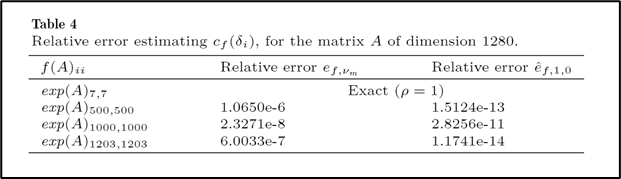

*Table from Page 152 of the paper*

${\textrm{expA}}_{\left(7,7\right)}$, 1 term estimate:

cf = e7' * expA * e7

cf = 7.3891

c0 = e7' * e7;
c1 = e7' * A * e7;
c2 = e7' * A * A * e7;
ro = (c0*c2)/(c1^2)

ro = 1


vm = 1

vm = 1

estimate_1 = exp((ro^vm) * c1 / c0) * c0

estimate_1 = 7.3891

format long
relative_error_1term = abs((estimate_1 - cf)/cf)

relative_error_1term =      1.322220657942400e-15


format short

Here, since $\rho =1$, the one-term estimate gives the exact value for cf.

Relative error for 1 term estimate = `1.322220657942400e-15 (orders of magnitude smaller)`

Relative error result from paper = 0

${\textrm{expA}}_{\left(500,500\right)}$, 1 term estimate:


cf = e500' * expA * e500

cf = 1.0027

c0 = e500' * e500;
c1 = e500' * A * e500;
c2 = e500' * A * A * e500;
ro = (c0*c2)/(c1^2);

lambda_1 = Lambda_A(1280,1280);
lambda_p = Lambda_A(1,1);
vm_lower = 0

vm_lower = 0

vm_higher = log(lambda_1 * c0/c1)/log(ro)

vm_higher = 64.8482 + 0.0000i

vm = (vm_lower + vm_higher) / 2;
estimate_1 = exp((ro^vm) * c1 / c0) * c0;
relative_error1 = abs((estimate_1 - cf)/cf);

vm_paper = 0.00397170884

vm_paper = 0.0040

estimate_1_paper = exp((ro^vm_paper) * c1 / c0) * c0

estimate_1_paper = 1.0027 - 0.0000i

format long
relative_error_1term_paper = abs((estimate_1_paper - cf)/cf)

relative_error_1term_paper =      1.064999986267014e-06


format short

- vm theoretical lower limit = 0

- vm theoretical upper limit =` 64.8482`

- vm used in paper = 0.00397170884

Relative error for 1 term estimate = `1.064999986267014e-06`

Relative error from paper = 1.0650e-6

${\textrm{expA}}_{\left(500,500\right)}$, 2 term estimate:

cf = e500' * expA * e500

cf = 1.0027

c0 = e500' * e500;
c1 = e500' * A * e500;
c2 = e500' * A * A * e500;
c3 = e500' * A * A * A * e500;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * exp(l1) + x2 * exp(l2)

estimate_2 = 1.0027 - 0.0000i

format long
relative_error_2term = abs((estimate_2 - cf)/cf)

relative_error_2term =      1.519091186117782e-13


format short

Relative error for 2 term estimate = `1.5191e-13`

Relative error from paper = 1.5124e-13

${\textrm{expA}}_{\left(1000,1000\right)}$, 1 term estimate:

cf = e1000' * expA * e1000

cf = 1.0000

c0 = e1000' * e1000;
c1 = e1000' * A * e1000;
c2 = e1000' * A * A * e1000;
ro = (c0*c2)/(c1^2);

lambda_1 = Lambda_A(1280,1280);
lambda_p = Lambda_A(1,1);
vm_lower = 0

vm_lower = 0

vm_higher = log(lambda_1 * c0/c1)/log(ro)

vm_higher = 1.9369 - 0.0000i

vm = (vm_lower + vm_higher) / 2;
estimate_1 = exp((ro^vm) * c1 / c0) * c0;
relative_error1 = abs((estimate_1 - cf)/cf);

vm_paper = 0.003124936532726

vm_paper = 0.0031

estimate_1_paper = exp((ro^vm_paper) * c1 / c0) * c0

estimate_1_paper = 1.0000 + 0.0000i

format long
relative_error_1term_paper = abs((estimate_1_paper - cf)/cf)

relative_error_1term_paper =      2.327099993263553e-08


format short

- vm theoretical lower limit = 0

- vm theoretical upper limit =` 1.9369`

- vm used in paper = 0.003124936532726

Relative error for 1 term estimate = `2.327099993263553e-08`

Relative error from paper = 2.3271e-8

${\textrm{expA}}_{\left(1000,1000\right)}$, 2 term estimate:


cf = e1000' * expA * e1000

cf = 1.0000

c0 = e1000' * e1000;
c1 = e1000' * A * e1000;
c2 = e1000' * A * A * e1000;
c3 = e1000' * A * A * A * e1000;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * exp(l1) + x2 * exp(l2)

estimate_2 = 1.0000 + 0.0000i

format long
relative_error_2term = abs((estimate_2 - cf)/cf)

relative_error_2term =      2.841390984259099e-11


format short

Relative error for 2 term estimate = `2.841390984259099e-11`

Relative error from paper = 2.8256e-11

${\textrm{expA}}_{\left(1203,1203\right)}$, 1 term estimate:

cf = e1203' * expA * e1203

cf = 1.0024

c0 = e1203' * e1203;
c1 = e1203' * A * e1203;
c2 = e1203' * A * A * e1203;
ro = (c0*c2)/(c1^2);

lambda_1 = Lambda_A(1280,1280);
lambda_p = Lambda_A(1,1);
vm_lower = 0

vm_lower = 0

vm_higher = log(lambda_1 * c0/c1)/log(ro)

vm_higher = 1.0079e+02 - 1.4925e-29i

vm = (vm_lower + vm_higher) / 2;
estimate_1 = exp((ro^vm) * c1 / c0) * c0;
relative_error1 = abs((estimate_1 - cf)/cf);

vm_paper = 0.003735722209011

vm_paper = 0.0037

estimate_1_paper = exp((ro^vm_paper) * c1 / c0) * c0

estimate_1_paper = 1.0024 + 0.0000i

format long
relative_error_1term_paper = abs((estimate_1_paper - cf)/cf)

relative_error_1term_paper =      6.003299998604722e-07


format short

- vm theoretical lower limit = 0

- vm theoretical upper limit = `1.0079e+02`

- vm used in paper = 0.003735722209011

Relative error for 1 term estimate = `6.003299998604722e-07`

Relative error from paper = 6.0033e-7

${\textrm{expA}}_{\left(1203,1203\right)}$, 2 term estimate:

cf = e1203' * expA * e1203

cf = 1.0024

c0 = e1203' * e1203;
c1 = e1203' * A * e1203;
c2 = e1203' * A * A * e1203;
c3 = e1203' * A * A * A * e1203;

r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
l1 = (r + (r^2 - 4*q)^0.5)/2 ;
l2 = (r - (r^2 - 4*q)^0.5)/2 ;
x1 = (c0*l2 - c1) / (l2 - l1);
x2 = (c1 - c0*l1) / (l2 - l1);
estimate_2 = x1 * exp(l1) + x2 * exp(l2)

estimate_2 = 1.0024 + 0.0000i

format long
relative_error_2term = abs((estimate_2 - cf)/cf)

relative_error_2term =      1.750038832051139e-14


format short

Relative error for 2 term estimate = `1.750038832051139e-14`

Relative error from paper = 1.1741e-14

#### (IV)Table 7: Trace estimation

Estimation of the bilinear form y*Ax helps us calculating the trace of matrix f(A). This in turn can be used to estimate the partial eigenvalue sum of matrix A, by choosing appropriate function f(A) and estimate the trace of f(A). Calculating partial eigenvalue sum has applications in solid state physics.

Partial eigenvalue sum of Hermitian matrix A is the sum of the eigen values of A that are less than or equal to a given real number $\mu$.

*Trace estimation formula:* 

*Expression from page 153 of the paper*

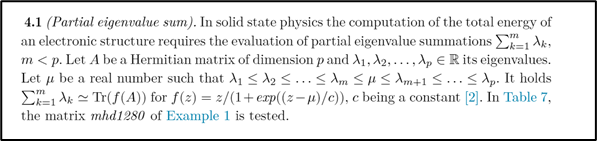

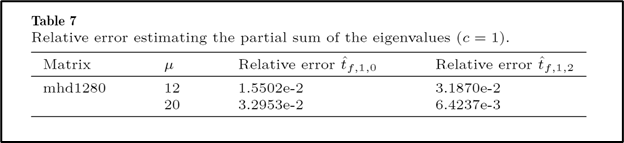

*Excerpts from page 154 of the paper*

As mentioned earlier, since the algorithm for estimating trace uses randomized choices for x, the following results for relative error may not be the same as that of the paper. But they are close in terms of order of magnitude. Each execution of the program gives a different result due to the randi function used in the code.

#### Column I: n = 1, k = 0

Trace12 = trace(Lambda_B)

Trace12 = 243.1356

Trace20 = trace(Lambda_C)

Trace20 = 259.0684

t_estimate12 = 0;
t_estimate20 = 0;
alphabet = [-1 1]';

for n = 1:50
    idx = randi([1 numel(alphabet)], 1280, 1);
    x = alphabet(idx);
    c0 = x' * x;
    c1 = x' * A * x;
    c2 = x' * A * A * x;
    c3 = x' * A * A * A * x;
    r = (c0*c3 - c2*c1)/(c0*c2 - c1*c1);
    q = (c1*c3 - c2*c2)/(c0*c2 - c1*c1);
    l1 = (r + (r^2 - 4*q)^0.5)/2 ;
    l2 = (r - (r^2 - 4*q)^0.5)/2 ;
    x1 = (c0*l2 - c1) / (l2 - l1);
    x2 = (c1 - c0*l1) / (l2 - l1);
    estimate_2_12 = (x1 * l1/(1 + exp(l1 - 12))) + (x2 * l2/(1 + exp(l2 - 12)));
    t_estimate12 = t_estimate12 + (estimate_2_12/50);
    estimate_2_20 = (x1 * l1/(1 + exp(l1 - 20))) + (x2 * l2/(1 + exp(l2 - 20)));
    t_estimate20 = t_estimate20 + (estimate_2_20/50);
end
t_estimate12

t_estimate12 = 2.4495e+02 + 6.7224e-23i

relative_error_mu12_n1_k0 = abs((t_estimate12 - Trace12)/Trace12)

relative_error_mu12_n1_k0 = 0.0075

t_estimate20

t_estimate20 = 2.4548e+02 + 1.0586e-22i

relative_error_mu20_n1_k0 = abs((t_estimate20 - Trace20)/Trace20)

relative_error_mu20_n1_k0 = 0.0525

- $\mu$ = 12 :

Relative error for $t_{f,1,0}$ obtained =` 0.0075`

Relative error for $t_{f,1,0}$ from paper = 1.5502e-2

- $\mu$ = 20 :

Relative error for $t_{f,1,0}$ obtained =` 0.0525`

Relative error for $t_{f,1,0}$ from paper = 3.2953e-2

#### Column II: n = 1, k = 2

Trace12 = trace(Lambda_B)

Trace12 = 243.1356

Trace20 = trace(Lambda_C)

Trace20 = 259.0684

t_estimate12 = 0;
t_estimate20 = 0;
alphabet = [-1 1]';

for n = 1:50
    idx = randi([1 numel(alphabet)], 1280, 1);
    x = alphabet(idx);
    c0 = x' * x;
    c1 = x' * A * x;
    c2 = x' * A * A * x;
    c3 = x' * A * A * A * x;
    c4 = x' * A * A * A * A * x;
    c5 = x' * A * A * A * A * A * x;
    
    r = (c0*c5 - c2*c3)/(c0*c4 - c1*c3);
    q = (c1*c5 - c2*c4)/(c0*c4 - c1*c3);
    l1 = (r + (r^2 - 4*q)^0.5)/2 ;
    l2 = (r - (r^2 - 4*q)^0.5)/2 ;
    x1 = (c0*l2 - c1) / (l2 - l1);
    x2 = (c1 - c0*l1) / (l2 - l1);
    estimate_2_12 = (x1 * l1/(1 + exp(l1 - 12))) + (x2 * l2/(1 + exp(l2 - 12)));
    t_estimate12 = t_estimate12 + (estimate_2_12/50);
    estimate_2_20 = (x1 * l1/(1 + exp(l1 - 20))) + (x2 * l2/(1 + exp(l2 - 20)));
    t_estimate20 = t_estimate20 + (estimate_2_20/50);
end
t_estimate12

t_estimate12 = 2.6399e+02 + 1.1570e-22i

relative_error_mu12_n1_k2 = abs((t_estimate12 - Trace12)/Trace12)

relative_error_mu12_n1_k2 = 0.0858

t_estimate20

t_estimate20 = 2.6399e+02 + 1.1570e-22i

relative_error_mu20_n1_k2 = abs((t_estimate20 - Trace20)/Trace20)

relative_error_mu20_n1_k2 = 0.0190

- $\mu$ = 12 :

Relative error for $t_{f,1,2}$ obtained =` 0.0858`

Relative error for $t_{f,1,2}$ from paper = 3.1870e-2

- $\mu$ = 20 :

Relative error for $t_{f,1,2}$ obtained = `0.0190`

Relative error for $t_{f,1,2}$ from paper =  6.4237e-3

### References

[1] Fika, P., Mitrouli, M., 2016. Estimation of the bilinear form y⁎f(A)x for Hermitian matrices. Linear Algebra and its Applications 502, 140–158.

[2] [MHD1280B: Alfven Spectra in Magnetohydrodynamics](https://math.nist.gov/MatrixMarket/data/NEP/mhd/mhd1280b.html)

[3] M. Hutchinson, A stochastic estimator of the trace of the influence matrix for Laplacian smoothing splines, Comm. Statist. Simulation 18 (1989) 1059–1076.

## Thank you